# ENERGY CONSUMPTION PREDICTION

[Rebeca Estrada](https://orcid.org/0000-0003-3957-9294), [Víctor Asanza](https://orcid.org/0000-0002-2786-4162),[ Danny Torres](https://orcid.org/0000-0003-2752-7489), [Adrian Bazurto](https://orcid.org/0000-0003-4144-1948), [Irving Valeriano](https://orcid.org/0000-0002-3539-5482)

- Main Code: [https://github.com/vasanza/EnergyConsumptionPrediction](https://github.com/vasanza/EnergyConsumptionPrediction)

- `DataPort: `[https://dx.doi.org/10.21227/x6jw-m015](https://dx.doi.org/10.21227/x6jw-m015)

- `Reference: `[10.1109/SAS51076.2021.9530151](https://doi.org/10.1109/SAS51076.2021.9530151)

- Sampling Rate=1Hz

- Date = '2021-05-06 00:00:00' AND '2021-11-22 22:04:21'

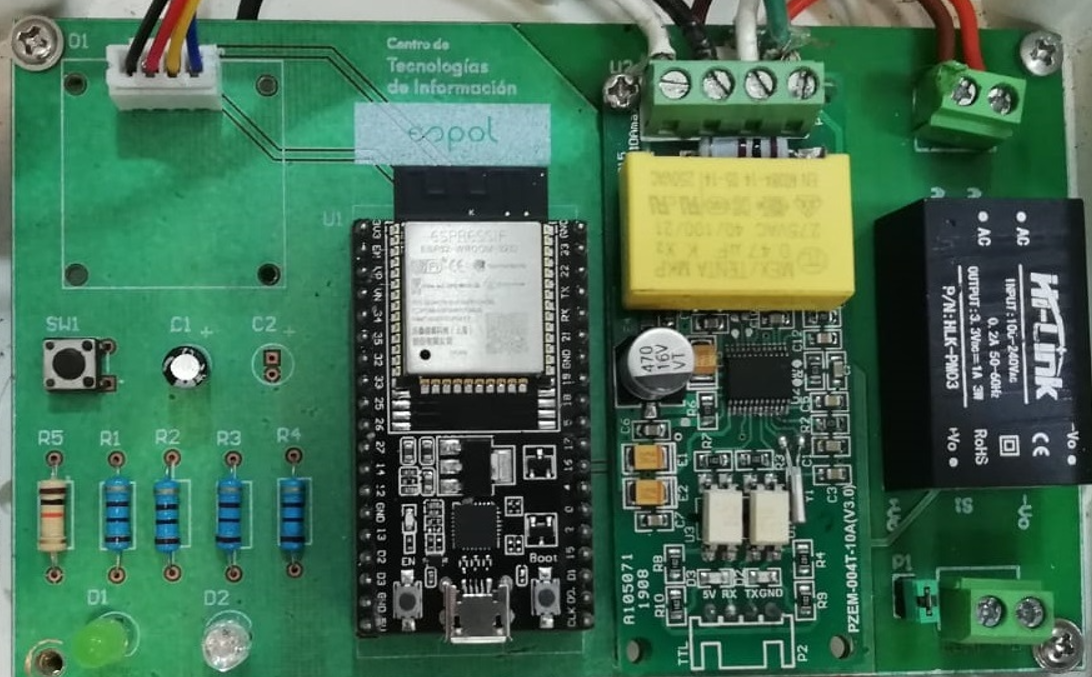

# 1- Load Raw Data

clear;clc;%clear all
%Prepare the raw dataset
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder
filenames = FindCSV(datapath);%List All CSV files
allData=[];
for i=1:length(filenames)% Through all files
    data=readtable(fullfile(datapath,filenames(i).name));%Select i CSV file
    %The first 3 columns are deleted: topic, server date, esp32 date, and esp32 date.
    data=[data(:,2) data(:,5:end)];
    dataNew=table2array(data);% Array Double
    dataNew(isnan(dataNew)) = 0;%Remove NAN numbers
    allData=[allData;dataNew];
end
clear data dataNew;

# 2- Every 60 samples the value of 1 minute is averaged

win=60;% 1 minute
%It takes time to iterate the number of samples / time window.
allDataMean = fData_MeanWin(allData,win);
%save(fullfile(datapath,'allData.mat'),'allData');%No es posible para datos
%mayores a 2GB
save(fullfile(datapath,'allDataMean.mat'),'allDataMean');
clear allData win

# 3- Plot Raw Data (Dataset)

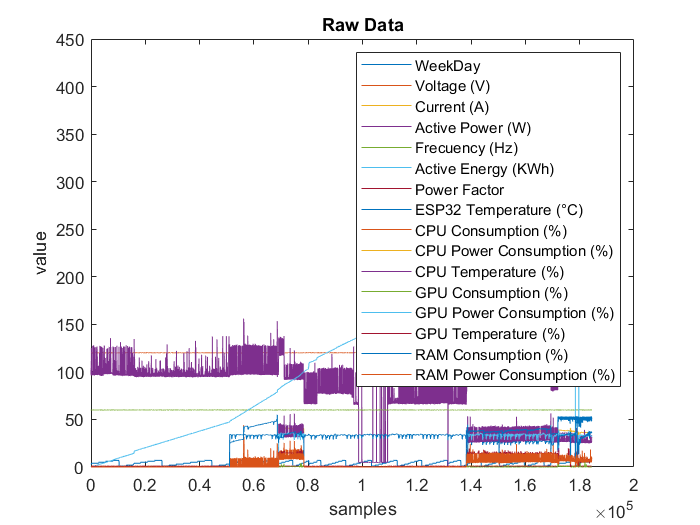

figure
plot(allDataMean);title('Raw Data');xlabel('samples');ylabel('value');
legend('WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)','Power Factor',...
    'ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)','GPU Consumption (%)'...
    ,'GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)');

# 4- Preprocessing: Data Normalization and Plot Normalization Dataset


allDataNorm = fNormalization(allDataMean);%Normalization
%'Active Energy (KWh)'
[AEds] = datastats(allDataMean(:,6))

AEds = struct with fields:
       num: 184426
       max: 432.5034
       min: 0.0062
      mean: 122.3349
    median: 127.9700
     range: 432.4971
       std: 82.8325


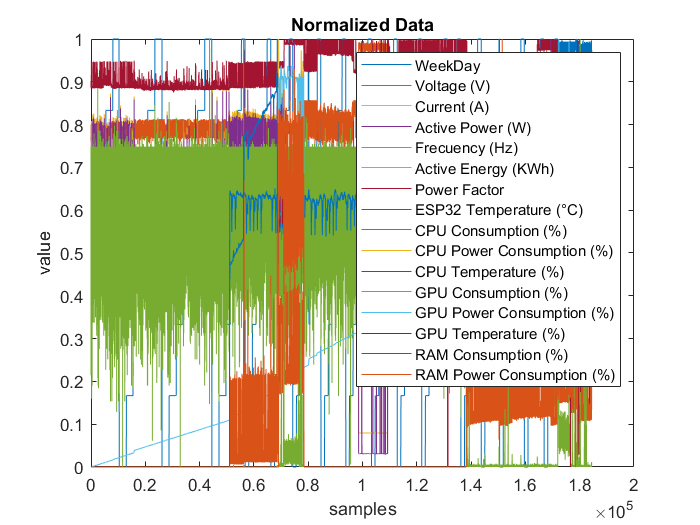

figure
plot(allDataNorm);title('Normalized Data');xlabel('samples');ylabel('value');
legend('WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)',...
    'Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)'...
    ,'GPU Consumption (%)','GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)');

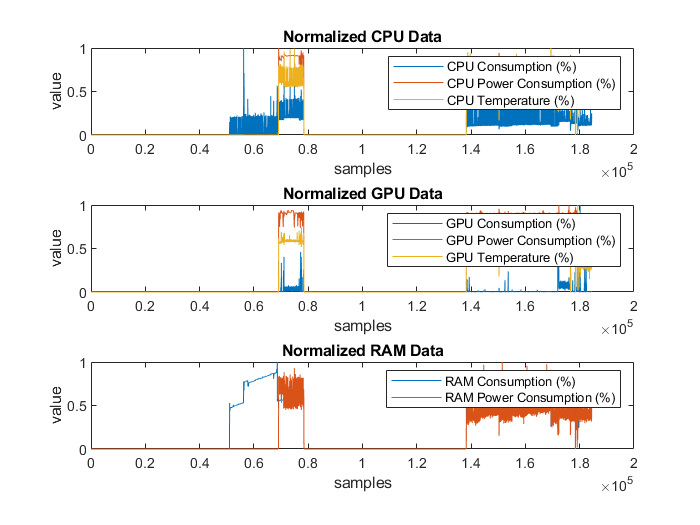

figure
subplot(3,1,1)
plot(allDataNorm(:,9:11));title('Normalized CPU Data');xlabel('samples');ylabel('value');
legend('CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)');
subplot(3,1,2)
plot(allDataNorm(:,12:14));title('Normalized GPU Data');xlabel('samples');ylabel('value');
legend('GPU Consumption (%)','GPU Power Consumption (%)','GPU Temperature (%)');
subplot(3,1,3)
plot(allDataNorm(:,15:16));title('Normalized RAM Data');xlabel('samples');ylabel('value');
legend('RAM Consumption (%)','RAM Power Consumption (%)');

# 5- Statital Information Raw Data (Dataset)

%WeekDay','Voltage (V)'
[wds,vds] = datastats(allDataNorm(:,1),allDataNorm(:,2))

wds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.5172
    median: 0.5000
     range: 1
       std: 0.3314


vds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.7777
    median: 0.7916
     range: 1
       std: 0.1199


%'Current (A)','Active Power (W)'
[cds,pds] = datastats(allDataNorm(:,3),allDataNorm(:,4))

cds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.5788
    median: 0.6525
     range: 1
       std: 0.1643


pds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.5562
    median: 0.6057
     range: 1
       std: 0.1626


%'Frecuency (Hz)','Active Energy (KWh)'
[fds,eds] = datastats(allDataNorm(:,5),allDataNorm(:,6))

fds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.6163
    median: 0.6258
     range: 1
       std: 0.0865


eds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.2828
    median: 0.2959
     range: 1
       std: 0.1915


%'Power Factor','ESP32 Temperature (°C)'
[pfds,tds] = datastats(allDataNorm(:,7),allDataNorm(:,8))

pfds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.8857
    median: 0.9219
     range: 1
       std: 0.1431


tds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.4519
    median: 0.5982
     range: 1
       std: 0.2982


%'CPU Consumption (%)','CPU Power Consumption (%)'
[cpuds,cpupds] = datastats(allDataNorm(:,9),allDataNorm(:,10))

cpuds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.0454
    median: 0
     range: 1
       std: 0.0723


cpupds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.2548
    median: 0
     range: 1
       std: 0.3896


%'CPU Temperature (%)',%'GPU Consumption (%)'
[cputds,gpuds] = datastats(allDataNorm(:,11),allDataNorm(:,12))

cputds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.1535
    median: 0
     range: 1
       std: 0.2373


gpuds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.0041
    median: 0
     range: 1
       std: 0.0211


%'GPU Power Consumption (%)','GPU Temperature (%)'
[gpupds,gputds] = datastats(allDataNorm(:,13),allDataNorm(:,14))

gpupds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.2631
    median: 0
     range: 1
       std: 0.4024


gputds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.1556
    median: 0
     range: 1
       std: 0.2449


%'RAM Consumption (%)','RAM Power Consumption (%)'
[ramds,rampds] = datastats(allDataNorm(:,15),allDataNorm(:,16))

ramds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.2691
    median: 0
     range: 1
       std: 0.3360


rampds = struct with fields:
       num: 184426
       max: 1
       min: 0
      mean: 0.1387
    median: 0
     range: 1
       std: 0.2210


clear wds vds cds pds fds eds pfds tds cpuds cpupds cputds gpuds gpupds gputds ramds rampds

# [6] - Feature Extraction (Please set TimeStep per time window)

%clear;clc;%clear all
%Prepare the raw dataset
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder
allDataMean = load(fullfile(datapath,'allDataMean.mat'));%List All CSV files
allDataMean=allDataMean.allDataMean;
AEds = datastats(allDataMean(:,6))

AEds = struct with fields:
       num: 184426
       max: 432.5034
       min: 0.0062
      mean: 122.3349
    median: 127.9700
     range: 432.4971
       std: 82.8325



% Select only one TimeStep
%TimeStep =40320;% one month in minutes (only 8 monthss)
%TimeStep =10080;% one week in minutes
%TimeStep =1440;% one day in minutes
TimeStep =60;% one hour in minutes
%TimeStep =1;% one minute

DataFeatures = frms_features_v2(allDataMean,TimeStep);

# 7 - Feature Selection (Please set the maximum correlation value allowed.)

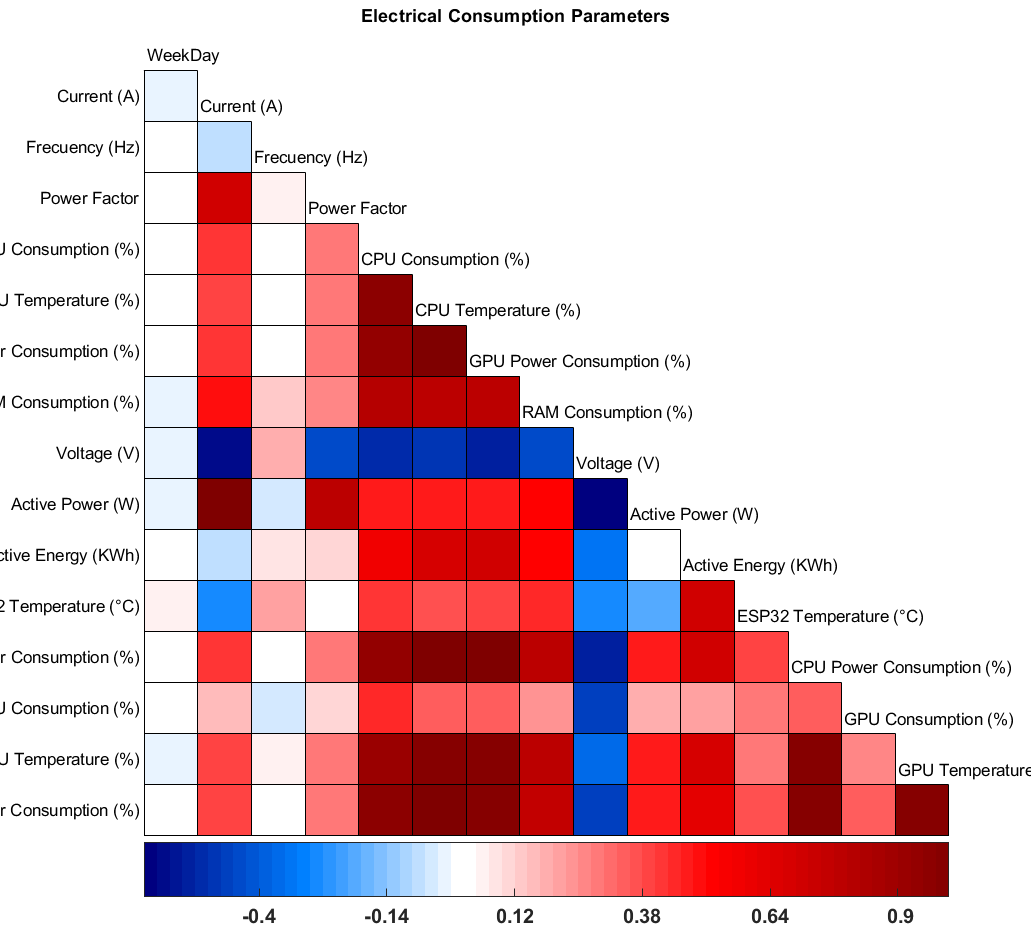

threshold = 0.750;%<-------Maximum correlation value allowed
% Labels:
FeaturesLabels = {'WeekDay','Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)','Power Factor',...
    'ESP32 Temperature (°C)','CPU Consumption (%)','CPU Power Consumption (%)','CPU Temperature (%)','GPU Consumption (%)'...
    ,'GPU Power Consumption (%)','GPU Temperature (%)','RAM Consumption (%)','RAM Power Consumption (%)'};
[NewDataFeatures,NewFeaturesLabels,LabelsRemove] = Feature_Selection(DataFeatures,FeaturesLabels,threshold);

LabelsRemove(:)

ans = 8×1 cell array
    {'Active Power (W)'         }
    {'Power Factor'             }
    {'CPU Power Consumption (%)'}
    {'CPU Temperature (%)'      }
    {'GPU Power Consumption (%)'}
    {'GPU Temperature (%)'      }
    {'RAM Consumption (%)'      }
    {'RAM Power Consumption (%)'}


clear threshold LabelsRemove

# 8 - Regression Learner (Input output Data)

training_size=0.85; %70 Training, 15% Validation
testing_size=1-training_size;%15% Testing
Cell_Active_Energy=strfind(NewFeaturesLabels, 'Active Energy (KWh)');
ind_Active_Energy = find(not(cellfun('isempty',Cell_Active_Energy)));
% inputs: All previously selected features
input_train=NewDataFeatures(1:round(length(NewDataFeatures)*training_size)-1,:);
% output: Energy in the next time step
output_train=NewDataFeatures(1+1:round(length(NewDataFeatures)*training_size),...
    ind_Active_Energy);%Active Energy index 5
regressionLearner
clear Cell_Active_Energy testing_size Features_labels

# RMSE (Validation): 1 month

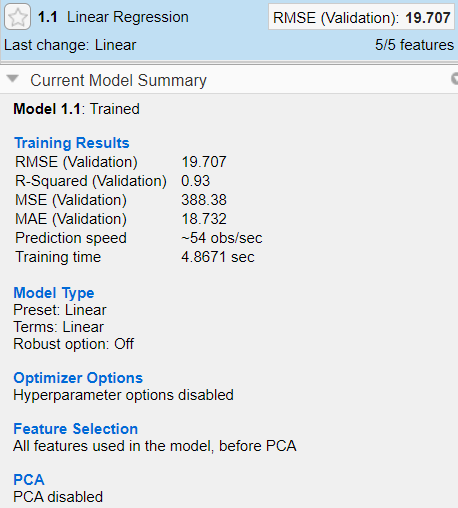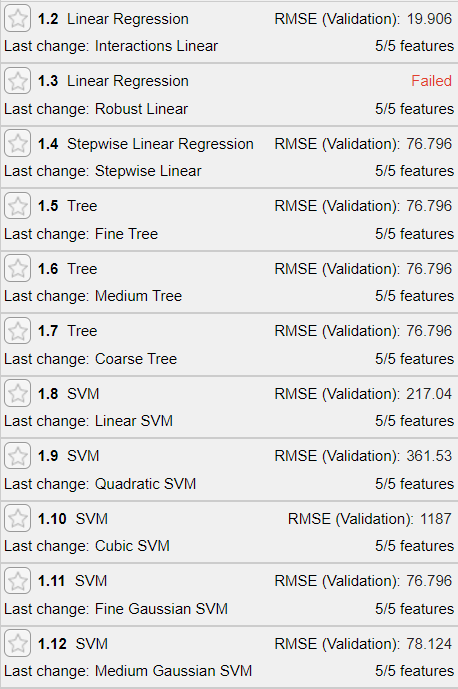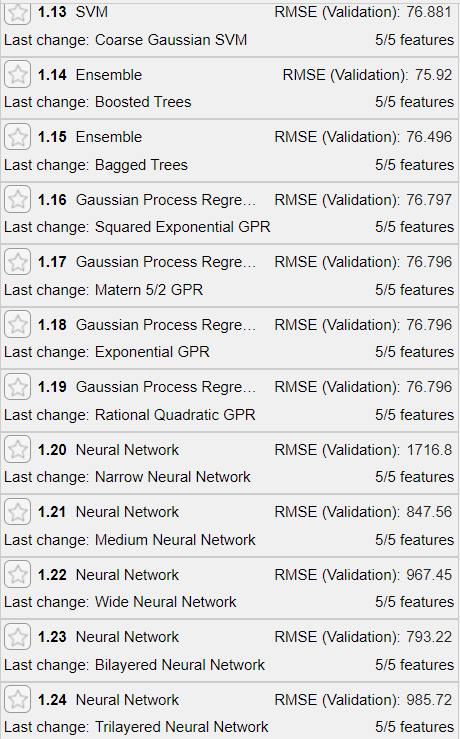

# RMSE (Validation): 1 Week

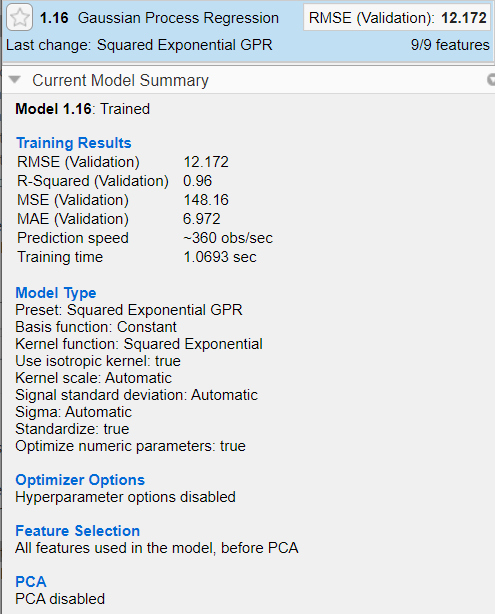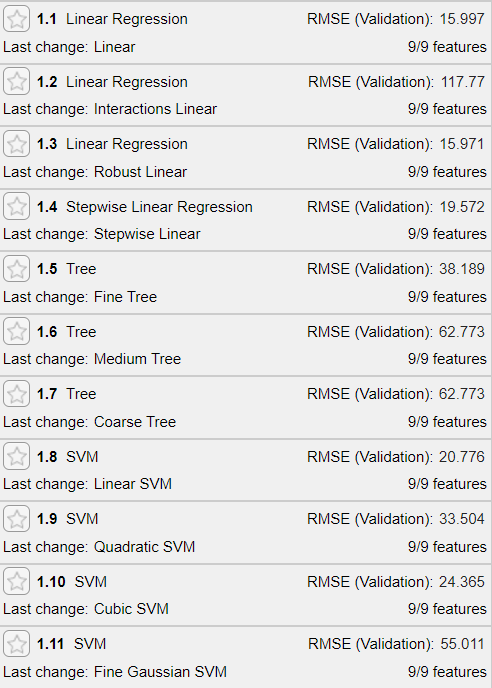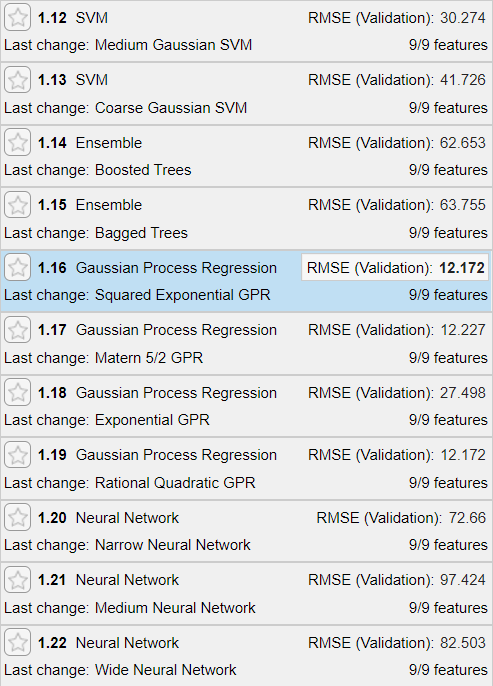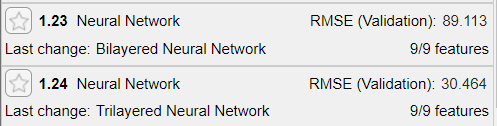

# RMSE (Validation): 1 day 

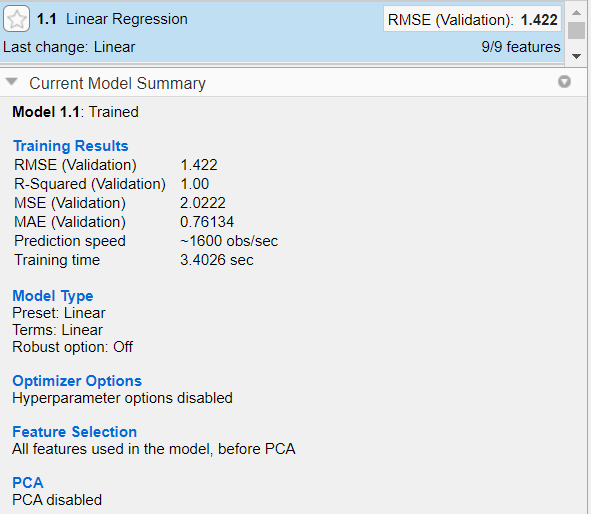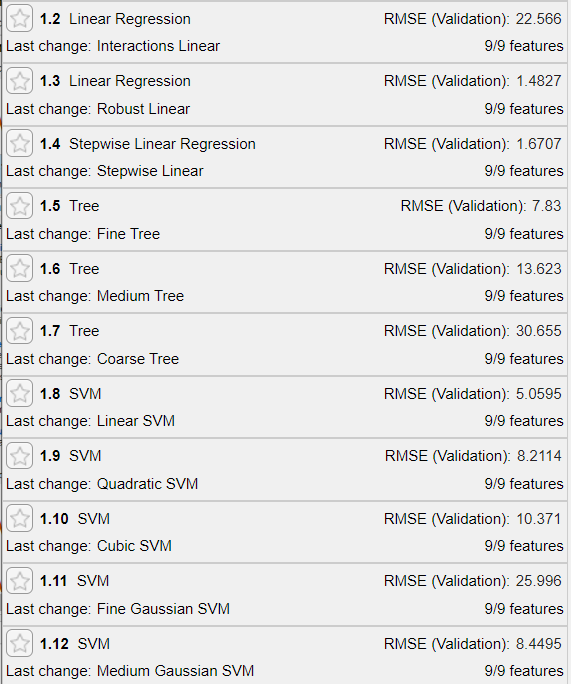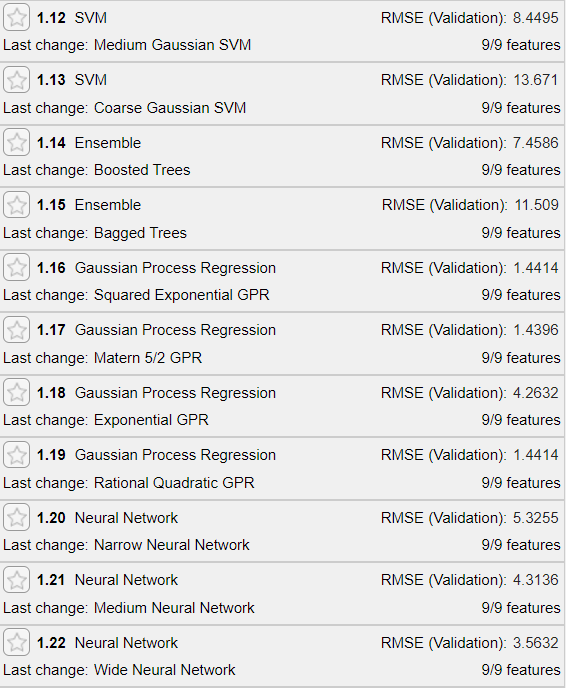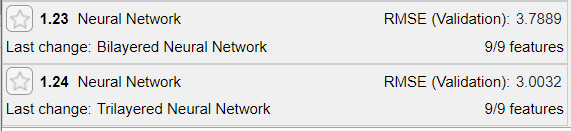

# RMSE (Validation): 1 hour

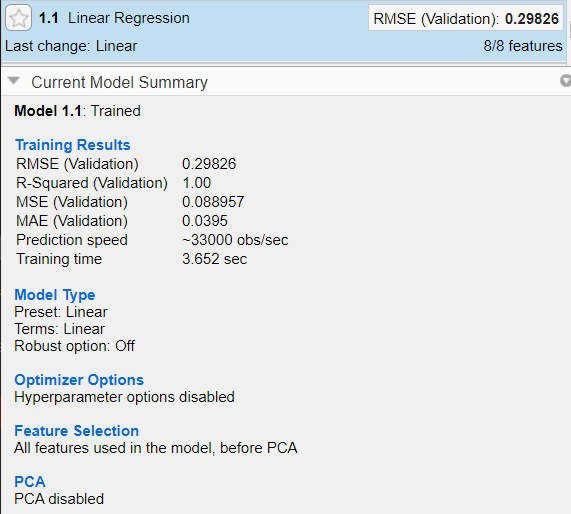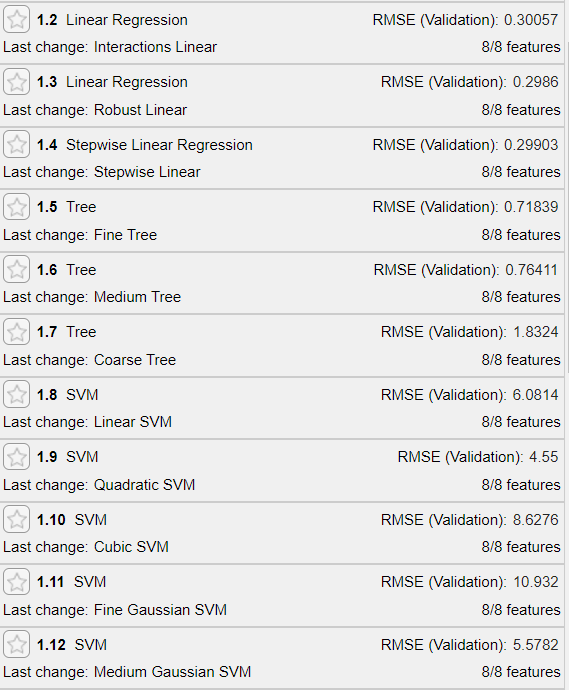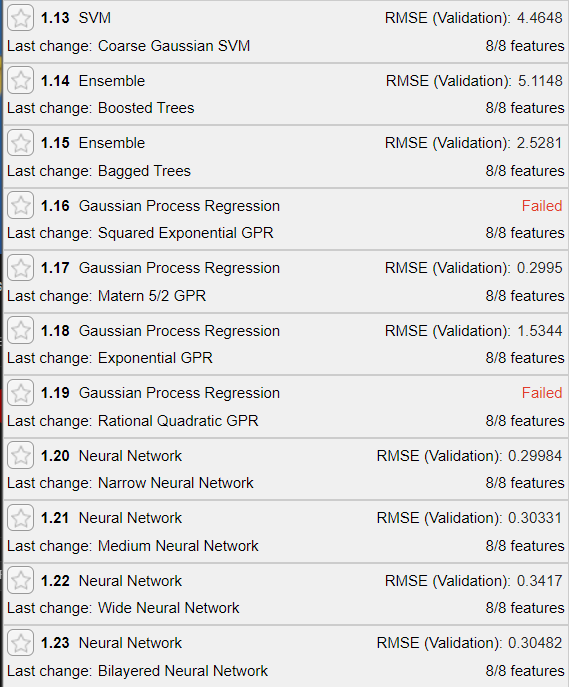

# RMSE (Validation): 1 minute

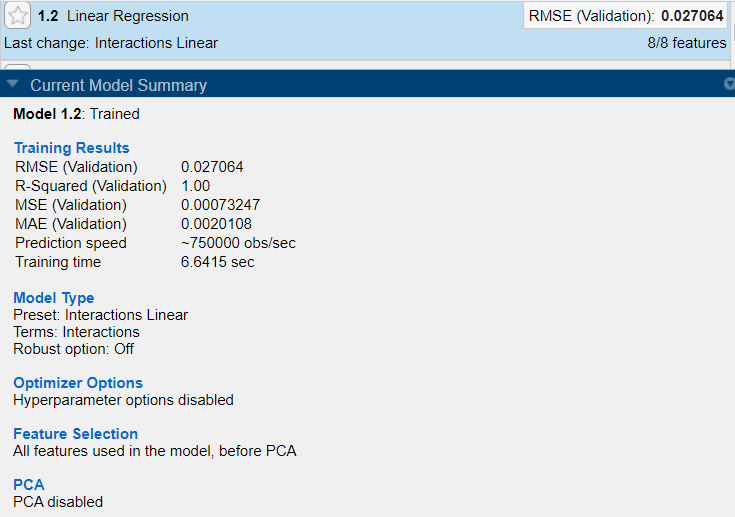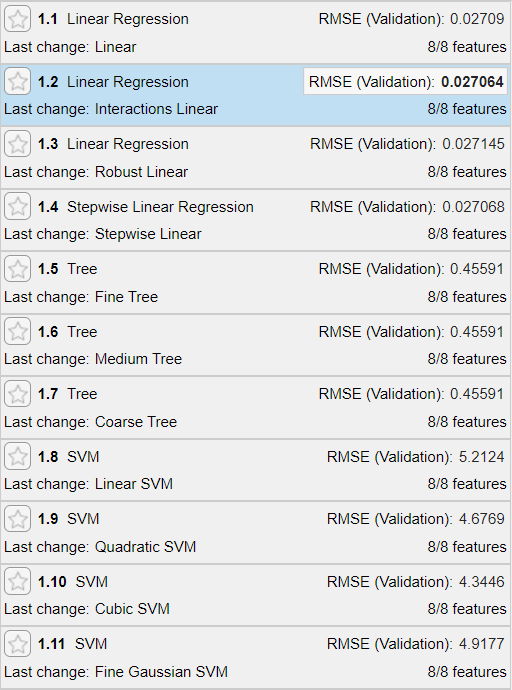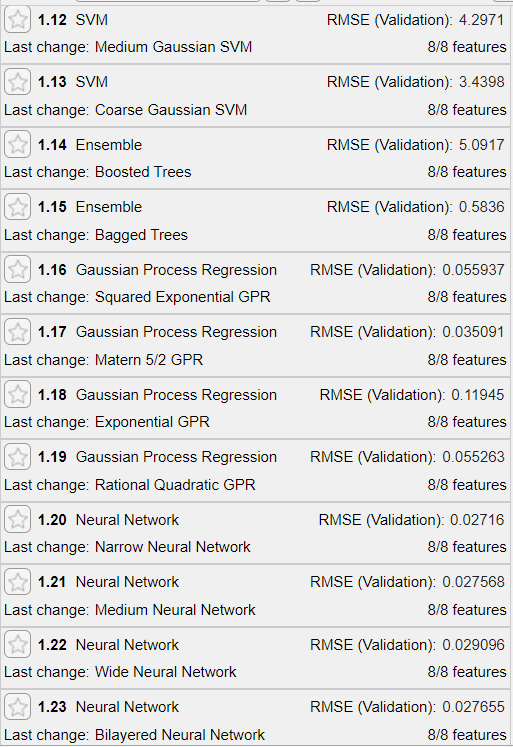

# RMSE (Testing): 1 week

% input: Energy
input_val=NewDataFeatures(round(length(NewDataFeatures)*training_size):length(NewDataFeatures)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(length(NewDataFeatures)*training_size)+1:length(NewDataFeatures)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
[model_week, RMSE_week] = trainRegressionModel_week(input_train, output_train);
RMSE_week

RMSE_week = 13.5883

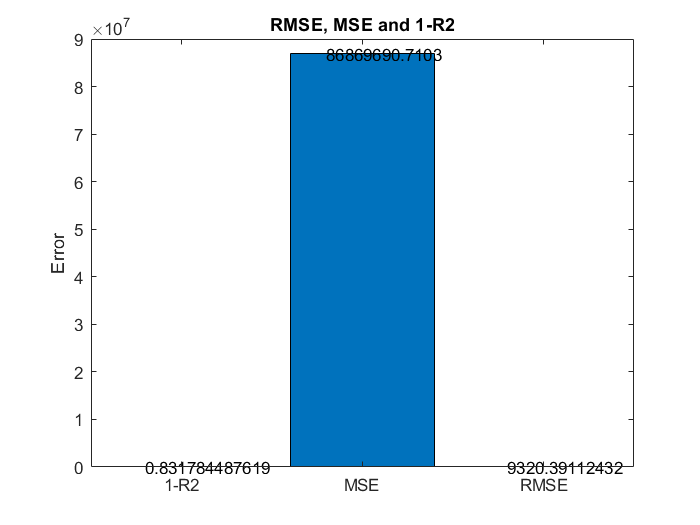

estimate_week=model_week.predictFcn(input_val);
estimate_week=fDenormalize(estimate_week,AEds.max,AEds.min);
output_week=fDenormalize(output_val,AEds.max,AEds.min);
[rmse_week,mse_week,R2_week]=fBar_RmseMseR2(estimate_week,output_week);

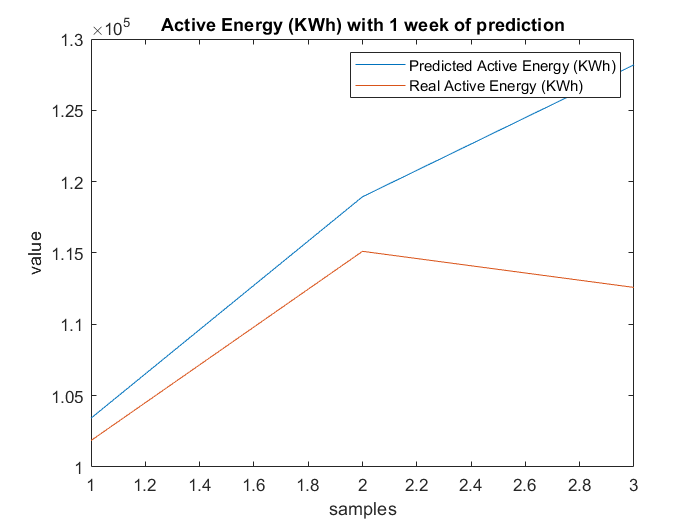

figure
plot([estimate_week,output_week]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 week of prediction');

clear model_week RMSE_week output_week estimate_week

# RMSE (Testing): 1 day

% input: Energy
input_val=NewDataFeatures(round(length(NewDataFeatures)*training_size):length(NewDataFeatures)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(length(NewDataFeatures)*training_size)+1:length(NewDataFeatures)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
[model_day, RMSE_day] = trainRegressionModel_day2(input_train, output_train);
RMSE_day

RMSE_day = 1.4174

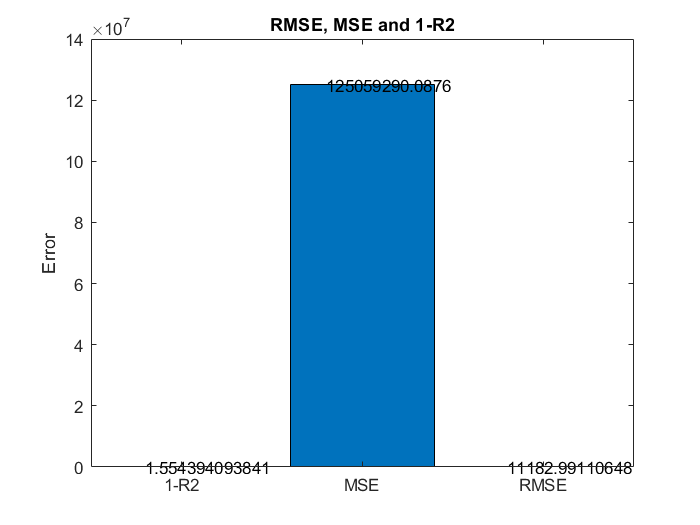

estimate_day=model_day.predictFcn(input_val);
estimate_day=fDenormalize(estimate_day,AEds.max,AEds.min);
output_day=fDenormalize(output_val,AEds.max,AEds.min);
[rmse_day,mse_day,R2_day]=fBar_RmseMseR2(estimate_day,output_day);

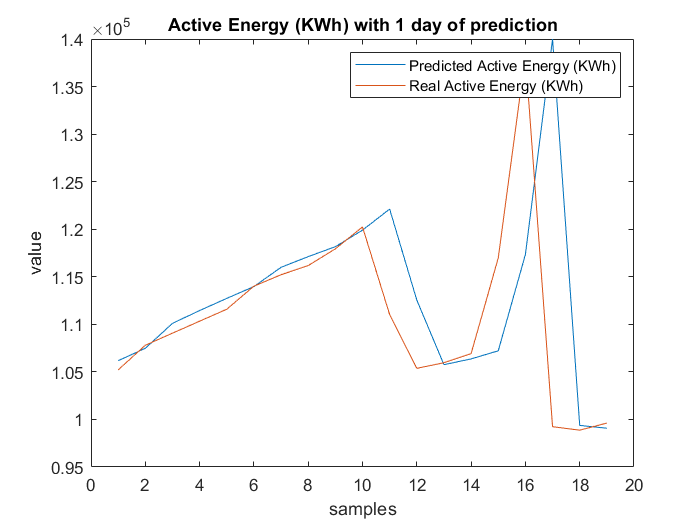

figure
plot([estimate_day,output_day]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 day of prediction');

clear model_day RMSE_day output_day estimate_day

# RMSE (Testing): 1 hour

% input: Energy
input_val=NewDataFeatures(round(length(NewDataFeatures)*training_size):length(NewDataFeatures)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(length(NewDataFeatures)*training_size)+1:length(NewDataFeatures)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
[model_hour, RMSE_hour] = trainRegressionModel_hour(input_train, output_train);
RMSE_hour

RMSE_hour = 0.2982

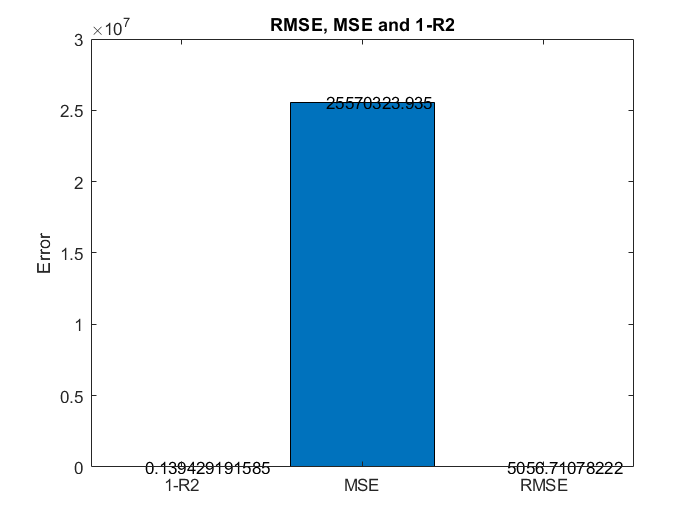

estimate_hour=model_hour.predictFcn(input_val);
estimate_hour=fDenormalize(estimate_hour,AEds.max,AEds.min);
output_hour=fDenormalize(output_val,AEds.max,AEds.min);
[rmse_hour,mse_hour,R2_hour]=fBar_RmseMseR2(estimate_hour,output_hour);

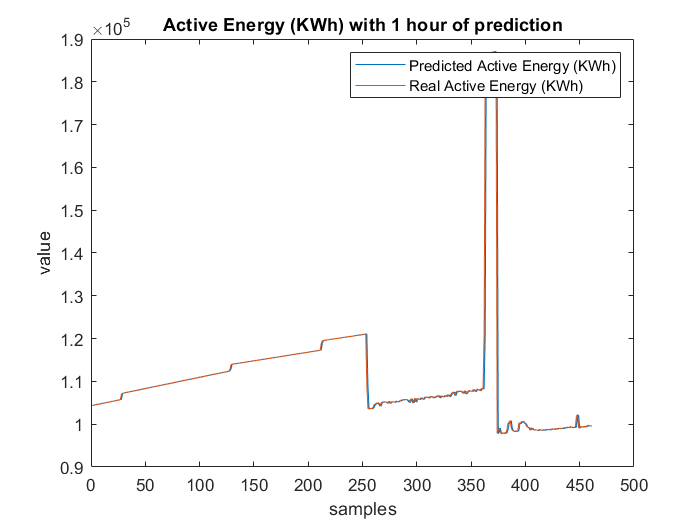

figure
plot([estimate_hour,output_hour]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 hour of prediction');

clear model_hour RMSE_hour output_hour estimate_hour

# RMSE (Testing): minute

% input: Energy
input_val=NewDataFeatures(round(length(NewDataFeatures)*training_size):length(NewDataFeatures)-1,:);
% output: Energy in the next time step
output_val=NewDataFeatures(round(length(NewDataFeatures)*training_size)+1:length(NewDataFeatures)...
    ,ind_Active_Energy);%Active Energy index 5
% Generate model
[model_minute, RMSE_minute] = trainRegressionModel_minute(input_train, output_train);
RMSE_minute

RMSE_minute = 0.3009

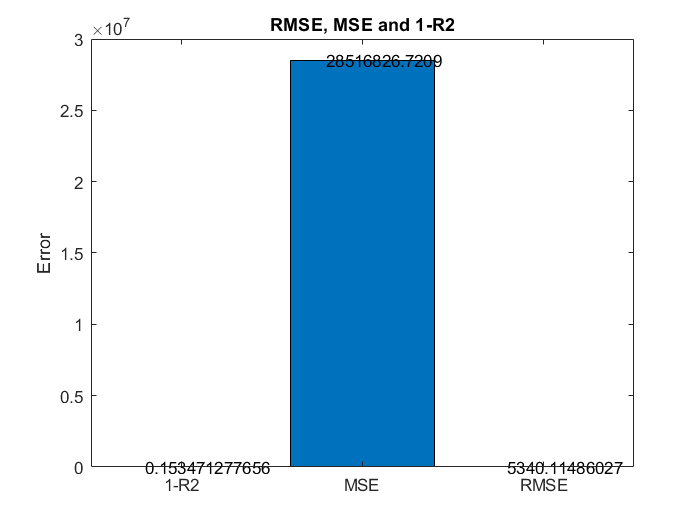

estimate_minute=model_minute.predictFcn(input_val);
estimate_minute=fDenormalize(estimate_minute,AEds.max,AEds.min);
output_minute=fDenormalize(output_val,AEds.max,AEds.min);
[rmse_minute,mse_minute,R2_minute]=fBar_RmseMseR2(estimate_minute,output_minute);

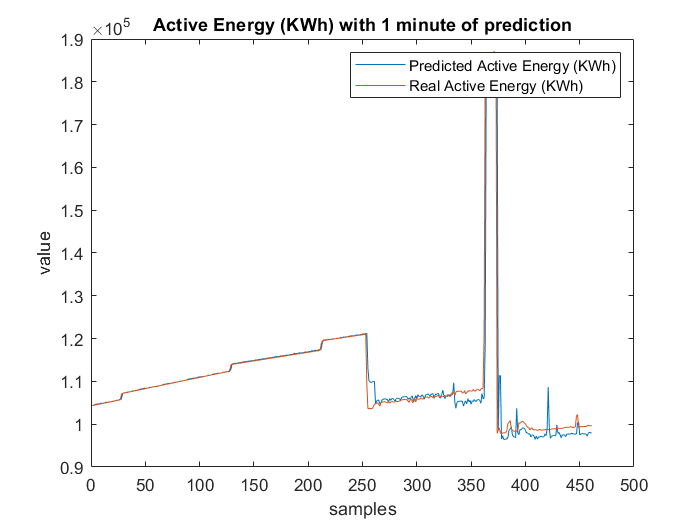

figure
plot([estimate_minute,output_minute]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 minute of prediction');

clear model_minute RMSE_minute output_minute estimate_minute

# Summary RMSE (Testing): Week, Day, Hour and Min 

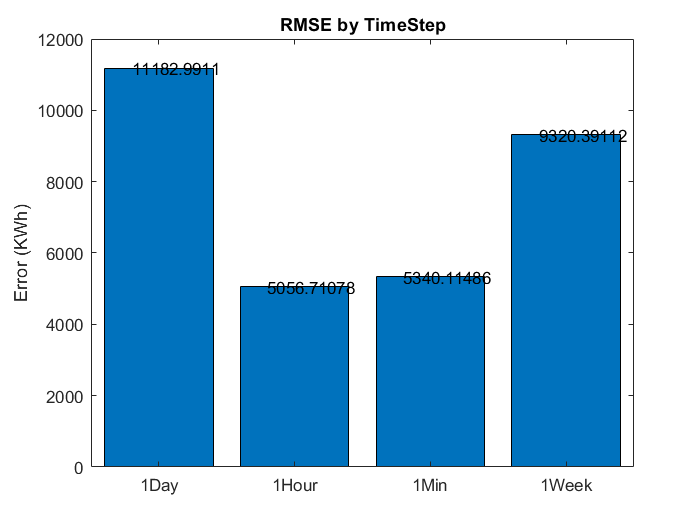

    c = categorical({'1Week','1Day','1Hour','1Min'});
    values = [rmse_week rmse_day rmse_hour rmse_minute];%rmse
    figure;
    b=bar(c,values);
    ylabel('Error (KWh)')
    title('RMSE by TimeStep')
    xtips1 = b(1).XEndPoints - 0.2;
    ytips1 = b(1).YEndPoints + 0.0003;
    labels1 = string(b(1).YData);
    text(xtips1,ytips1,labels1,'VerticalAlignment','middle')

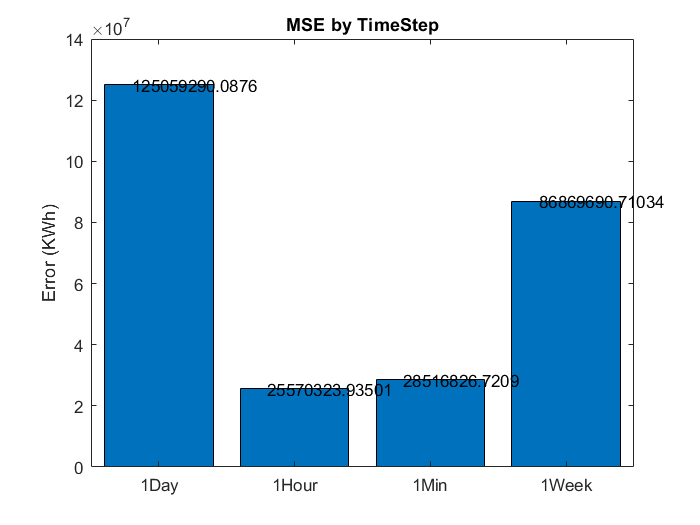

    
    values = [mse_week mse_day mse_hour mse_minute];%mse
    figure;
    b=bar(c,values);
    ylabel('Error (KWh)')
    title('MSE by TimeStep')
    xtips1 = b(1).XEndPoints - 0.2;
    ytips1 = b(1).YEndPoints + 0.0003;
    labels1 = string(b(1).YData);
    text(xtips1,ytips1,labels1,'VerticalAlignment','middle')

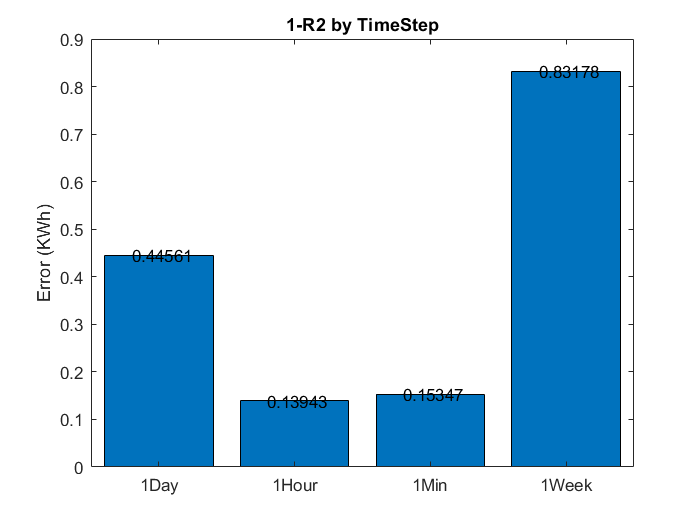

    
    values = [1-R2_week 1+R2_day 1-R2_hour 1-R2_minute];%1-R2
    figure;
    b=bar(c,values);
    ylabel('Error (KWh)')
    title('1-R2 by TimeStep')
    xtips1 = b(1).XEndPoints - 0.2;
    ytips1 = b(1).YEndPoints + 0.0003;
    labels1 = string(b(1).YData);
    text(xtips1,ytips1,labels1,'VerticalAlignment','middle')

# FutureWork

%Continue to record more data on more workstations.
%Create a model for estimating memory and CPU consumption since there are spaces without these values.
%Make a real time consumption prediction system.